% 构建常微分方程组：1.因变量y（1）可以出现在方程的左边；2.dz代表dy(1)/dt,即方程的左侧可以不出现自变量t
clear,clc,close all
tspan = [0,30];
p = 10;
r = 28;
b = 3;
y0 = [0 1 0];
[t,J] = ode45(@(t,y) ode(t,y,p,r,b), tspan, y0) %J代表输出的自变量所构成的矩阵

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0002


J =          0    1.0000         0
    0.0001    1.0000    0.0000
    0.0001    1.0000    0.0000
    0.0002    1.0000    0.0000
    0.0002    1.0000    0.0000
    0.0005    1.0000    0.0000
    0.0007    0.9999    0.0000
    0.0010    0.9999    0.0000
    0.0012    0.9999    0.0000
    0.0025    0.9998    0.0000


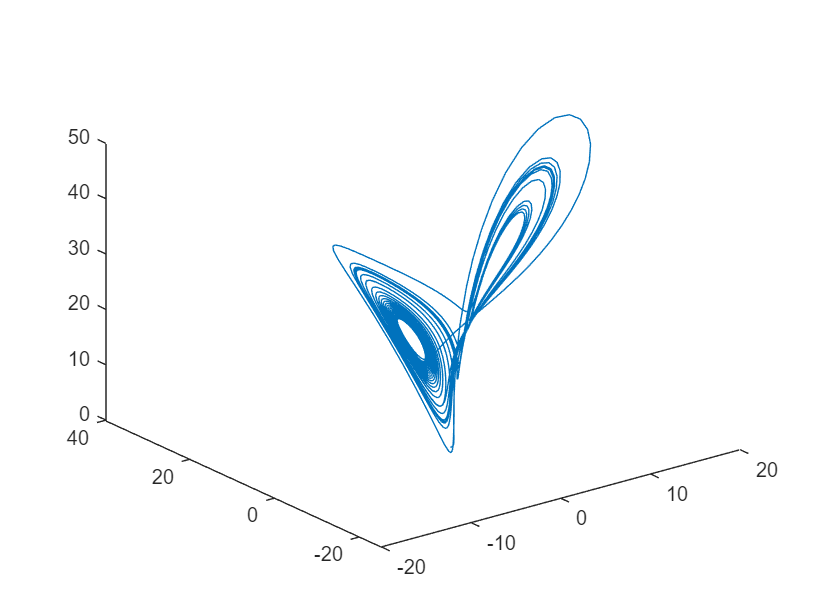


plot3(J(:,1),J(:,2),J(:,3))

function dz = ode(t,y,p,r,b)
dz = zeros(3,1); %构建dz的数列
dz(1) = p*(y(2)-y(1)); %y(1)代表方程1对应的因变量
dz(2) = y(1)*(r-y(3))-y(2); %y(2)代表方程2对应的因变量
dz(3) = y(1)*y(2)-b*y(3);  %y(3)代表方程3对应的因变量
end
